% Grey Evaluation
% by A.Beltrami

% Read the grey definition axis
GreyScale=[15; 30; 50; 70; 85];
n=size(GreyScale,1);
GreyAxis=zeros(n,8);
T = readtable('FOGRA51_GreyAxis.txt',"FileType","text")

T = 15×8 table
    SAMPLE_NAME    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L      LAB_A      LAB_B 
    ___________    ______    ______    ______    ______    ______    _______    _______

         5         3.5294    2.7451    2.7451      0       92.195     1.5078    -5.7617
        10          7.451    5.4902    5.4902      0       89.242     1.3594    -5.6602
        15         11.765    8.6275    8.2353      0        85.93      1.332    -5.6562
        20         15.686    11.373     10.98      0       82.973     1.1914    -5.4414
        25             20     14.51    14.118      0       79.692     1.1016    -5.1602
        30         23.922    17.647    17.255      0       76.624     1.0859    -4.8516
        

for i=1:n
    GreyAxis(i,:)=T(T.SAMPLE_NAME==GreyScale(i),:).Variables;
end

% Prepare arrays
n=size(GreyScale,1);
GreyReproduction=zeros(n,3);
DeltaE=zeros(n,1);
DeltaCh=zeros(n,1);
DeltaC=zeros(n,1);
Deltah=zeros(n,1);

% Load measures

%fileName="TVI Calibrated.txt";
fileName="11R_Grey_FD9.txt";

% Read CGATS files and extract L,a,b
meas = fopen(fileName);
line = '';
while strcmp(line,'BEGIN_DATA')==0
    line=fgetl(meas);
end
% Calculate the index pf the five central patches 
GreyScaleIndex=[round(7*7/2), 7*7+round(13*13/2), 7*7+13*13+round(13*13/2), 7*7+13*13*2+round(13*13/2), 7*7+13*13*3+round(7*7/2)]

GreyScaleIndex =     25   134   303   472   581


i=1;
while strcmp(line,'END_DATA')==0 && i<=n
    line=fgetl(meas);
    if strcmp(line,'END_DATA')
        break;
    end
    line=replace(line,',','.');
    values=textscan(line,'%d %s %f %f %f %*[^\n]'); %ID, NAME, L, a, b, 36*spectrum
    % Extract Lab of the five central patches
    if values{1}(1)==GreyScaleIndex(i)
        GreyReproduction(i,1)=values{3}; %L
        GreyReproduction(i,2)=values{4}; %a
        GreyReproduction(i,3)=values{5}; %b
        i=i+1;
    end
end

% Calc Deltas
for i=1:n
    Lab1=GreyAxis(i,6:8);
    Lab2=GreyReproduction(i,:);
    DeltaE(i)=DE00(Lab1,Lab2); 
    DeltaCh(i)=DCh(Lab1,Lab2);
    DeltaC(i)=DC(Lab1,Lab2);
    Deltah(i)=Dh(Lab1,Lab2);
end
% Calc the GI_H (Gray Index based on DH)
GI=mean(abs(DeltaC))*(std(Deltah)/(2*pi)+1);

% Write the resulting table
G = table(GreyAxis(:,1),GreyAxis(:,2),GreyAxis(:,3),GreyAxis(:,4),GreyAxis(:,5),...
    GreyAxis(:,6),GreyAxis(:,7),GreyAxis(:,8),GreyReproduction(:,1),GreyReproduction(:,2),GreyReproduction(:,3),...
    DeltaE,DeltaCh,DeltaC,Deltah,...
    'VariableNames',{'SAMPLE_NAME','CMYK_C','CMYK_M','CMYK_Y','CMYK_K',...
    'REF_LAB_L','REF_LAB_A','REF_LAB_B','LAB_L','LAB_A','LAB_B',...
    'DE00','DCh','DC','Dh'})

G = 5×15 table
    SAMPLE_NAME    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    REF_LAB_L    REF_LAB_A    REF_LAB_B    LAB_L     LAB_A      LAB_B      DE00      DCh        DC         Dh   
    ___________    ______    ______    ______    ______    _________    _________    _________    ______    ______    _______    ______    ______    _______    _______

        15         11.765    8.6275    8.2353      0         85.93         1.332      -5.6562     75.724    2.2715    -6.3122     7.127   

writetable(G,replace(fileName,'.txt','.stat.txt'),'FileType',"text");

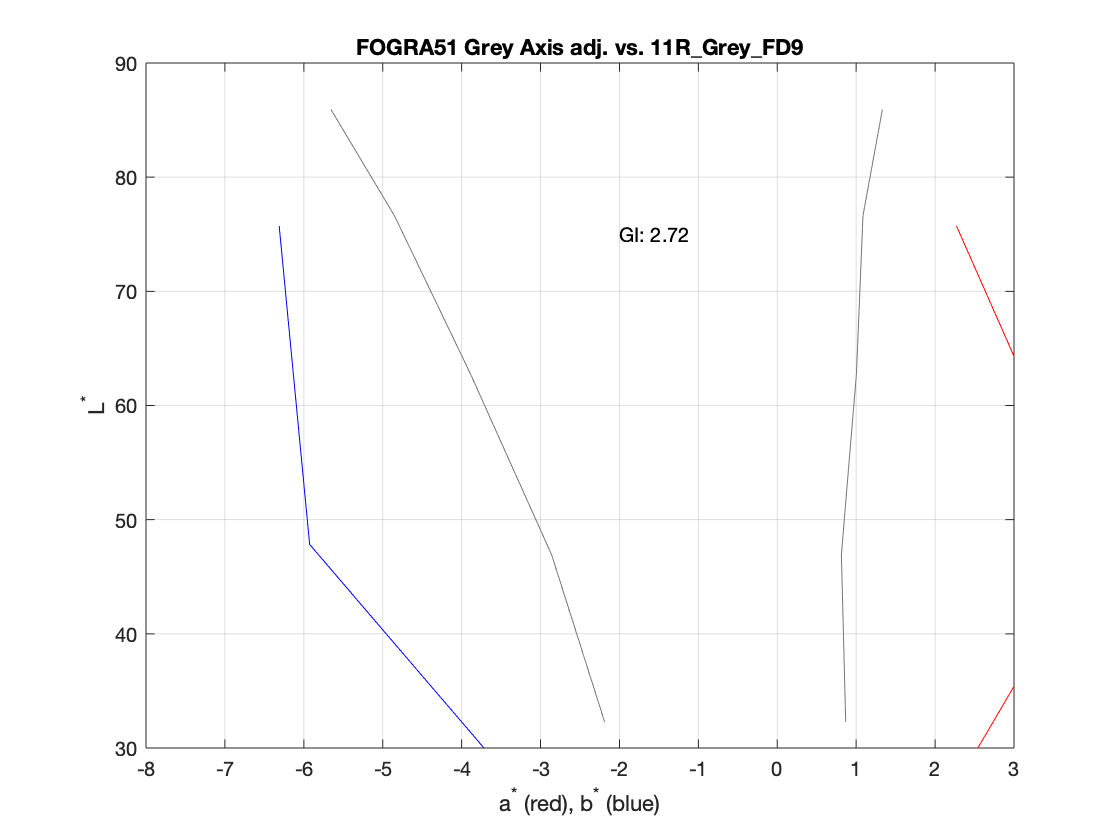

% Plot the target grey axis vs. the calculated grey axis
fig=figure;
p=plot(GreyAxis(:,7), GreyAxis(:,6), GreyAxis(:,8), GreyAxis(:,6),...
    GreyReproduction(:,2), GreyReproduction(:,1), GreyReproduction(:,3), GreyReproduction(:,1));
title(sprintf('FOGRA51 Grey Axis adj. vs. %s',replace(replace(fileName,'_','\_'),'.txt','')));
p(1).Color='#777777';
p(2).Color='#777777';
p(3).Color='r';
p(4).Color='b';
xlabel('a^* (red), b^* (blue)');
ylabel('L^*');
xlim([-8 3]);
ylim([30 90]);
grid on
text(-2,75,sprintf("GI: %.2f",GI));

saveas(fig,replace(fileName,'.txt','.png'),'png');